# Funciones matemáticas

MATLAB dispone de diversas funciones de distintas áreas de la matemática y todas estas funciones se encuentran vectorizadas, es decir, funcionan con escalares, vectores y matrices sin ningún problema.

**Figura 1.** Visualización de una función vectorizada.

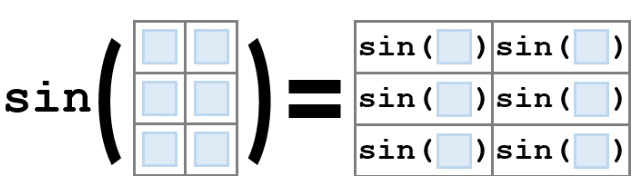

*Tomado de la documentación oficial de MATLAB.*

## Trigonometría

Las funciones trigonométricas de MATLAB calculan valores trigonométricos estándar en radianes o grados, valores trigonométricos hiperbólicos en radianes y otras variantes de cada función.

Para empezar hablaremos acerca de las funciones de conversión de grados a radianes.

### Funciones `rad2deg` y `deg2rad`

Es posible utilizar las funciones `rad2deg` (radianes a grados) y `deg2rad` (grados a radianes) para convertir entre radianes y grados, o viceversa.

angR=pi

angR = 3.1416

ang=rad2deg(angR)

ang = 180

deg2rad(ang)

ans = 3.1416

### Funciones `cart2pol` y `pol2cart`

Las funciones `cart2pol` (cartesiano a polar) y `pol2cart` (polar a cartesiano) permiten convertir vectores entre sistemas de coordenadas.

clear
x=[1 2 3 4 5 4];
y=[-8 0 1 2 3 3 ];
[theta,rho]=cart2pol(x,y)

theta =    -1.4464         0    0.3218    0.4636    0.5404    0.6435


rho =     8.0623    2.0000    3.1623    4.4721    5.8310    5.0000


[xnew,ynew]=pol2cart(theta,rho)

xnew =     1.0000    2.0000    3.0000    4.0000    5.0000    4.0000


ynew =    -8.0000         0    1.0000    2.0000    3.0000    3.0000


### Función `hypot`

La función `hypot` permite obtener la raíz cuadrada de la suma de los cuadrados de dos números, es decir, la hipotenusa.


$$h=\sqrt{a^2 +b^2 }$$


hypot(3,4)

ans = 5

### Funciones seno

MATLAB dispone de la función seno, su inversa, su hiperbólica y algunas variantes más.

**Figura 2.** Funciones seno dentro de MATLAB.

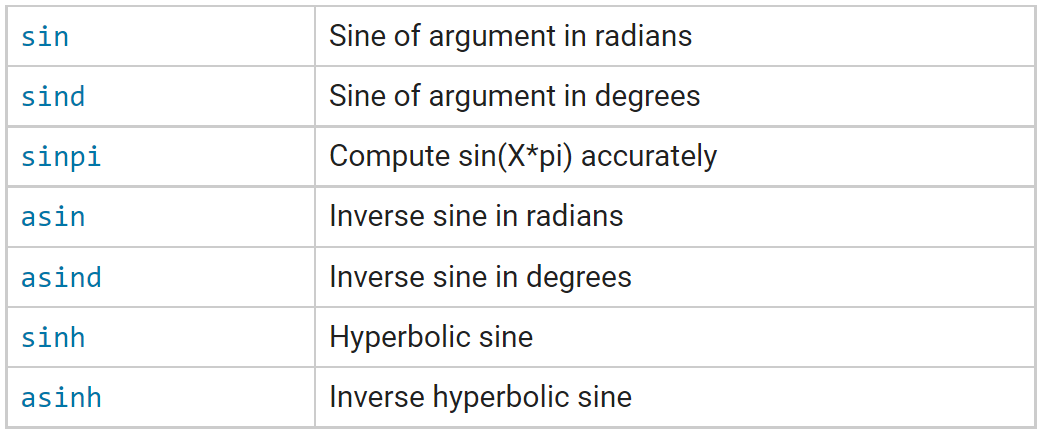

*Tomado de la documentación oficial de MATLAB.*

Veamos algunos ejemplos utilizando algunas de estas funciones.

sin(pi)

ans = 1.2246e-16

sind(180)

ans = 0

### Funciones coseno

MATLAB dispone de la función coseno, su inversa, su hiperbólica y algunas variantes más.

**Figura 3.** Funciones coseno dentro de MATLAB.

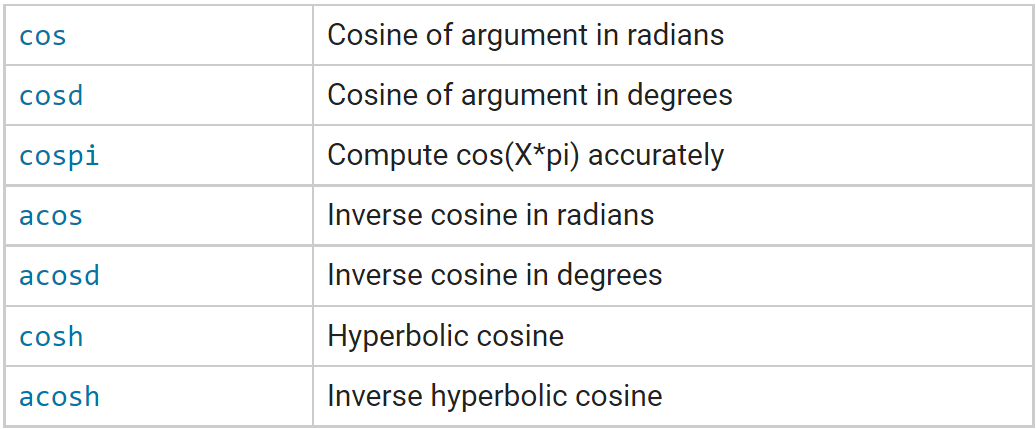

*Tomado de la documentación oficial de MATLAB.*

Veamos algunos ejemplos utilizando algunas de estas funciones.

cos(pi/2)

ans = 6.1232e-17

cosd(90)

ans = 0

### Funciones tangente

MATLAB dispone de la función coseno, su inversa, su hiperbólica y algunas variantes más.

**Figura 4.** Funciones tangente dentro de MATLAB.

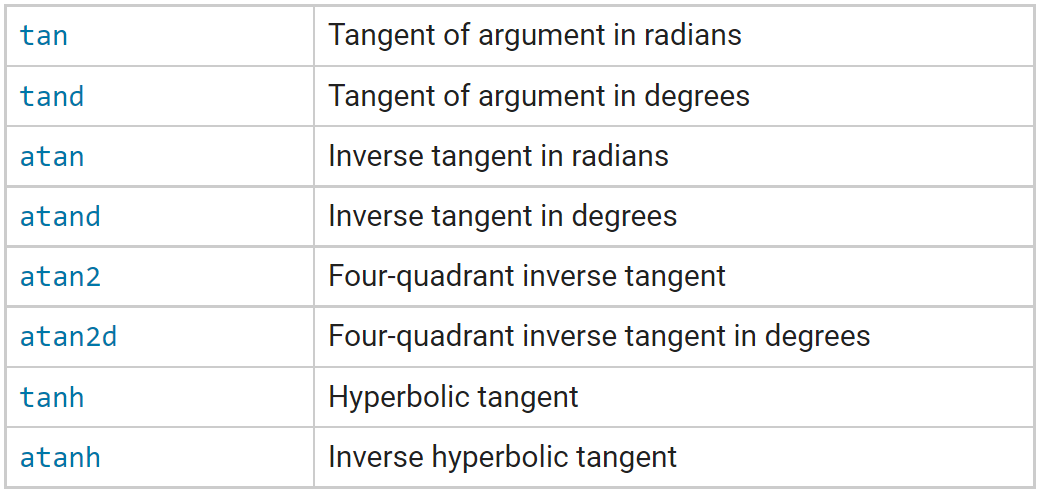

*Tomado de la documentación oficial de MATLAB.*

Veamos algunos ejemplos utilizando algunas de estas funciones.

tan(pi/2)

ans = 1.6331e+16

tand(90)

ans = Inf

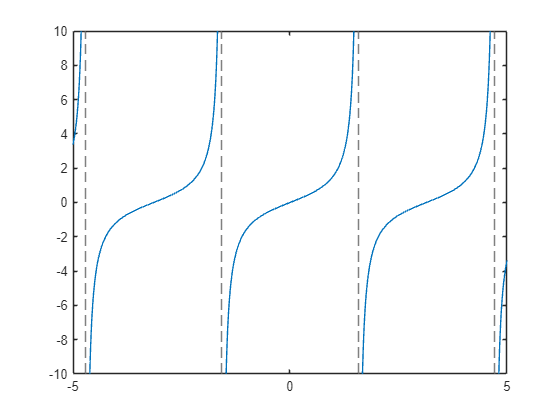

fplot(@tan)

### Más funciones trigonométricas

Este curso no está enfocado en el estudio de las funciones trigonométricas, por lo que se detallaron previamente las funciones más usuales. No obstante, si se desea profundizar el en el estudio de la trigonometría utilizando MATLAB, en el material adicional se adjuntó un enlace a la documentación de MATLAB acerca de la trigonometría.

## Exponentes y logaritmos

### Función `exp`

La función exponencial `exp` tiene como base el número de Euler $e$ y como pontencia el argumento que se le ingrese.

Debemos recordar que la función exponencial es $e^x$, es por eso que el número de Euler dentro de MATLAB se lo obtiene con esta función: `exp(1)`, lo cual vendría a significar $e^1$, pero esta expresión claramente es $e$.

exp(1)

ans = 2.7183

### Funciones `log, log2`  y `log10`

La función `log` permite determinar el logaritmo natural, o logaritmo neperiano, de un número.

No se debe confundir con la notación matemática $\ln \left(x\right)$, puesto que la función interna `ln` no existe.

log(exp(110))

ans = 110

Por otra parte, las funciones `log2` y `log10` permiten determinar el logaritmo en base 2 y en base 10, respectivamente, de un número.

log2(16)

ans = 4

log10(1000)

ans = 3

#### Observación

No existe una función que permita realizar el logaritmo de un número en una base en específico que no sean el número de Euler, el número 2 y el número 10. No obstante, es bastante sencillo construirla a partir de una función local o una función anónima, pero esto se lo discutirá más adelante.

### Funciones `sqrt` y `nthroot`

La función `sqrt` permite determinar la raíz cuadrada de un número. Si el número es negativo devolverá un número complejo.

sqrt(5)

ans = 2.2361

La función `nthroot` permite determinar la raíz *n-ésima* de un número.

nthroot(625,4)

ans = 5

## Matemática discreta

Las funciones matemáticas discretas realizan operaciones con números enteros $\left(\ldotp \ldotp \ldotp ,-2,-1,0,1,2,\ldotp \ldotp \ldotp \right)$ o devuelven una salida discreta como números enteros. Es posible utilizar estas funciones para factorizar números grandes, calcular factoriales, encontrar el máximo común denominador (m.c.m), etc.

### Función `factor` 

La función `factor` devuelve un vector en donde se encontrarán los factores primos del número.

factor(11)

ans = 11

factor(16)

ans =      2     2     2     2


### Funciones `primes` y `factorial`

La función `primes` permite determinar todos los números primos menores o iguales al número ingresado. Estos números los devuelven en un vector.

primes(10)

ans =      2     3     5     7


Por otra parte, la función `factorial` permite determinar el factorial de un número.

factorial(4)

ans = 24

### Funciones `gcd` y `lcm`

La función `gcd` permite deteminar el máximo común denominador (***g****reatest ****c****ommon ****d****ivisor*) de dos números.

gcd(20,10)

ans = 10

La función `lcm` permite determinar el mínimo común mútiplo (***l****east ****c****ommon ****m****ultiple*) de dos números.

lcm(20,10)

ans = 20

lcm(2,5)

ans = 10

## Números aleatorios

Los números aleatorios son extremadamente útiles para simular experimentos, procesos, generar datos de prueba, etc. A continuación se muestran las funciones más comunes.

### Funciones `rand` y `randi`

Las funciones `rand` y `randi` permiten generar números aleatorios uniformemente distribuidos. Es decir, los números generados tienen la misma probabilidad de salir, así como cuando se lanza una moneda: la probabilidad de que salga cara o sello es igual.

La diferencia entre la función `rand` y `randi` es:

- la función `rand` genera números aleatorios tomados de la distribución uniforme en el intervalo $\left\lbrack 0,1\right\rbrack$.

- la función `randi` genera números aleatorios enteros entre $\left\lbrack a,b\right\rbrack$, donde se puede especificar $a$ y $b$.

Veamos un par de ejemplos con la función `rand`.

rand(5,1)

ans =     0.0067
    0.6022
    0.3868
    0.9160
    0.0012


Veamos ahora ejemplos con la función `randi`.

randi(20)

ans = 10

randi(90,3,2)

ans =     39    30
    42    71
    70    43


### Función `randn`

La función `randn` permite generar números aleatorios obtenidos a partir de la distribución normal estándar con media $\mu =0$ y varianza $\sigma^2 =1$.

randn(3)

ans =    -2.0220   -0.0549    0.2495
   -0.9821   -1.1187   -0.9930
    0.6125   -0.6264    0.9750


## Estadística descriptiva

Si bien la estadística es una rama completa de estudio dentro de MATLAB, es importante conocer las funciones más utilizadas que no requieren mayor profundidad del tema.

### Funciones `max` y `min`

Las funciones `max` y `min` permiten conocer los números máximos y mínimos de una matriz, respectivamente.

El comportamiento de estas funciones depende de si el arreglo ingresado es una matriz o es un vector.

max([1 5 -5 5 8 ])

ans = 8

min([1 6 -9 4 32])

ans = -9

### Función `mean`

La función `mean` permite determinar la media arimética (también llamada *promedio*) de una matriz.

El comportamiento de esta función, al igual que las funciones `max` y `min`, depende de si el arreglo ingresado es una matriz o es un 

vector.

M=randi([10 100],5)

M =     70    65    38    68    57
    47    62    20    59   100
    86    59    95    68    29
    85    89    68    59    19
    33    34    53    75    19


promedio=mean(M,"all","omitmissing")

promedio = 58.2800

### Función `std`

La función `std` permite determinar la desviación estándar (también llamada *desviación típica*) de una matriz.

El comportamiento de esta función, al igual que las funciones anteriores, depende de si el arreglo ingresado es una matriz o es un vector.

M

M =     70    65    38    68    57
    47    62    20    59   100
    86    59    95    68    29
    85    89    68    59    19
    33    34    53    75    19


std(M,[],"all")

ans = 23.7004

## Material adicional

- [Matemática](https://www.mathworks.com/help/matlab/mathematics.html)

- [Trigonometría](https://www.mathworks.com/help/matlab/trigonometry.html)

- [Exponentes y logaritmos](https://www.mathworks.com/help/matlab/exponents-and-logarithms.html)

- [Matemática discreta](https://www.mathworks.com/help/matlab/discrete-math.html)

- [Generación de números aleatorios](https://www.mathworks.com/help/matlab/random-number-generation.html)

- [Estadística descriptiva](https://www.mathworks.com/help/matlab/descriptive-statistics.html)